year = 2024;   % Year of the calculation
month = 5;     % Month (May)
day = 25;      % Day (25th of the month)
hours = 16;    % Time of day in hours (16 hours = 4:00 PM)
minutes = 5;   % Minutes
seconds = 0;   % Seconds
tz = 5.5;      % Time zone (IST = UTC + 5.5 hours)
lat = 28;      % Latitude of the location (28 degrees)
long = 78;     % Longitude of the location (78 degrees)

% Create a datetime object for reference
dd = datetime(year, month, day, hours, minutes, seconds);

% Number of time steps (1 for each 1/24224 of a day)
num_steps = 24224; 

% Time step duration in seconds
time_step = 24 * 3600 / num_steps;  % 3.57 seconds

% Initialize arrays for elevation and azimuth angles
tilt_angles = zeros(1, num_steps);
azimuth_angles = zeros(1, num_steps);
Table = zeros(num_steps, 3);

for i = 1:num_steps
    % Calculate the time in hours for the current step
    current_time = (i - 1) * time_step;  % Time in seconds
    hours_passed = current_time / 3600;   % Convert to hours

    % Calculate the Julian date
    a = floor((14 - month) / 12);
    y = year + 4800 - a;
    m = month + 12 * a - 3;
    jd = day + floor((153 * m + 2) / 5) + 365 * y + floor(y / 4) - floor(y / 100) + floor(y / 400) - 32045;
    jd = jd + (hours + hours_passed - 12) / 24 + minutes / 1440 + seconds / 86400; 
    julian = jd - (tz / 24);

    % Calculate Julian century
    julian_cent = (julian - 2451545) / 36525;
    i2 = mod(280.46646 + julian_cent * (36000.76983 + julian_cent * 0.0003032), 360);
    j2 = 357.52911 + julian_cent * (35999.05029 - 0.0001537 * julian_cent);
    k2 = 0.016708634 - julian_cent * (0.000042037 + 0.0000001267 * julian_cent);

    % Calculate the sun's equation of the center
    l2 = sin(deg2rad(j2)) * (1.914602 - julian_cent * (0.004817 + 0.000014 * julian_cent)) + ...
         sin(deg2rad(2 * j2)) * (0.019993 - 0.000101 * julian_cent) + ...
         sin(deg2rad(3 * j2)) * 0.000289;
    m2 = i2 + l2;
    n2 = j2 + l2;
    o2 = (1.000001018 * (1 - k2 * k2)) / (1 + k2 * cos(deg2rad(n2)));
    p2 = m2 - 0.00569 - 0.00478 * sin(deg2rad(125.04 - 1934.136 * julian_cent));
    q2 = 23 + (26 + ((21.448 - julian_cent * (46.815 + julian_cent * (0.00059 - julian_cent * 0.001813)))) / 60) / 60;
    r2 = q2 + 0.00256 * cos(deg2rad(125.04 - 1934.136 * julian_cent));

    % Calculate the sun's right ascension
    s2 = rad2deg(atan2(cos(deg2rad(p2)), cos(deg2rad(r2)) * sin(deg2rad(p2))));
    t2 = rad2deg(asin(sin(deg2rad(r2)) * sin(deg2rad(p2))));

    % Calculate the equation of time
    u = tan(deg2rad(r2 / 2)) * tan(deg2rad(r2 / 2));
    v = 4 * rad2deg(u * sin(2 * deg2rad(i2)) - 2 * k2 * sin(deg2rad(j2)) + ...
                    4 * k2 * u * sin(deg2rad(j2)) * cos(2 * deg2rad(i2)) - ...
                    0.5 * u * u * sin(4 * deg2rad(i2)) - ...
                    1.25 * k2 * k2 * sin(2 * deg2rad(j2)));

    % Calculate the hour angle of sunrise
    w = rad2deg(acos(cos(deg2rad(90.833)) / (cos(deg2rad(lat)) * cos(deg2rad(t2))) - ...
                     tan(deg2rad(lat)) * tan(deg2rad(t2))));
    x = (720 - 4 * lat - v + tz * 60) / 1440;

    % Calculate sunrise and sunset times
    y2 = x - w * 4 / 1440;
    z2 = x + w * 4 / 1440;

    % Calculate the duration of sunlight in minutes
    aa = 8 * w;
    ab = mod((i - 1) * (24 * 60 / num_steps) + v + 4 * long - 60 * tz, 1440);
    ab2 = ab; 

    % Calculations for Elevation and Azimuth angles
    if ab2 / 4 < 0
        ac = ab2 / 4 + 180;
    else
        ac = ab2 / 4 - 180;
    end
    ad = rad2deg(acos(sin(deg2rad(lat)) * sin(deg2rad(t2)) + ...
                      cos(deg2rad(lat)) * cos(deg2rad(t2)) * cos(deg2rad(ac))));
    
    % Elevation angle 
    ae = 90 - ad;
    tilt_angles(i) = ae;

    if ac > 0
        ah = mod(rad2deg(acos(((sin(deg2rad(lat))*cos(deg2rad(ad)))-sin(deg2rad(t2)))/(cos(deg2rad(lat))*sin(deg2rad(ad)))))+180, 360);
    else
        ah = mod(540 - rad2deg(acos(((sin(deg2rad(lat))*cos(deg2rad(ad)))-sin(deg2rad(t2)))/(cos(deg2rad(lat))*sin(deg2rad(ad))))), 360);
    end
    % Azimuth angle
    azimuth_angles(i) = ah;

    % Integration in the format of a Table for Display
    Table(i, 1) = (i - 1) * time_step;  % Time in seconds
    Table(i, 2) = ae;
    Table(i, 3) = ah; 
    solar_ae(i) = ae;
    solar_az(i) = ah;
    % Changes done for Night time
    if tilt_angles(i) > 0
        tilt_angles(i) = 90 - tilt_angles(i); 
    end        

    if tilt_angles(i) <= 0
        azimuth_angles(i) = 0; 
        tilt_angles(i) = 90;
    end
end

% IRRADIANCE FOR FIXED PANEL REGONE
panel_azi_f = 180; % Facing south
panel_tilt_f = 15; % Fixed tilt angle, optimal angle for the panel

% Initialize the output
irradiance_fix = zeros(1, num_steps);

for i = 1:num_steps
     % Calculate irradiance for each hour
     irradiance_fix(i) = calculate_irradianc(solar_az(i), solar_ae(i), panel_azi_f, panel_tilt_f);
end


function irradiance = calculate_irradianc(solar_az, solar_ae, panel_azi_f, panel_tilt_f)
    % Check if the solar elevation is below the horizon
    if solar_ae <= 0
        irradiance = 0;
    else
        % Calculate the cosine of the angle of incidence
        cos_incident_theta = cosd(solar_ae)*cosd(90-panel_tilt_f)*cosd(solar_az-panel_azi_f)+sind(solar_ae)*sind(90-panel_tilt_f);
        irradiance = max(0, cos_incident_theta);
    end
end

% IRRADIANCE FOR SOLAR TRACKER
panel_tilt=transpose(panel_tilt);
panel_azi=transpose(panel_azi);
irradiance_track = zeros(1, num_steps);
% Loop over each time point to calculate irradiance
for i = 1:num_steps
    % Calculate the irradiance at each time step
    irradiance_track(i) = calculate_irradiance3(solar_az(i), solar_ae(i), panel_azi(i), panel_tilt(i));
end

% Function to calculate irradiance for each time point
function irradiance = calculate_irradiance3(solar_az, solar_ae, panel_azi, panel_tilt)
    % Check if the solar elevation is below the horizon
    if solar_ae < 0
        irradiance = 0;
    else
        % Calculate the cosine of the angle of incidence based on solar and panel angles
        cos_incident_theta = cosd(solar_ae) * cosd(90-panel_tilt) * cosd(solar_az - panel_azi) + sind(solar_ae) * sind(90-panel_tilt);
        % The irradiance is proportional to the cosine of the angle of incidence
        irradiance = max(0, cos_incident_theta);  % Ensure irradiance is not negative
    end
end

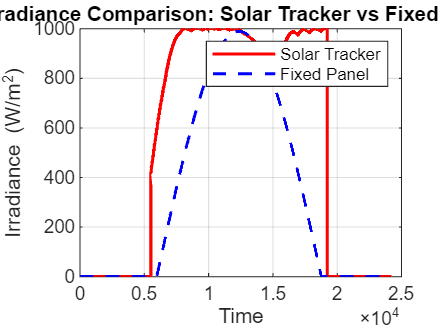

% Plot the irradiance for the solar tracker and fixed panel over time
figure;

% Plot irradiance for the solar tracker
plot(1:num_steps, irradiance_track*1000, 'r-', 'LineWidth', 1.5); 
hold on;

% Plot irradiance for the fixed panel
plot(1:num_steps, irradiance_fix*1000, 'b--', 'LineWidth', 1.5); 

% Add labels, title, and grid for better readability
xlabel('Time');
ylabel('Irradiance (W/m^2)');
title('Irradiance Comparison: Solar Tracker vs Fixed Panel');

% Add legend to distinguish the two plots
legend('Solar Tracker', 'Fixed Panel');

% Add grid for better visualization of data
grid on;

irradiance_fix_down = downscaled_array(irradiance_fix, 24);
irradiance_track_down = downscaled_array(irradiance_track, 24);
function downscaled_array = downscaled_array(original_array, new_size)
    % DOWNSCALE_ARRAY - Downscale an array by averaging segments of the array
    % downscaled_array = downscale_array(original_array, new_size)
    %
    % Inputs:
    %   original_array - The 1xN array to be downscaled
    %   new_size - The size of the downscaled array (1xM, where M < N)
    %
    % Output:
    %   downscaled_array - The downscaled array of size 1xM
    
    % Number of elements in the original array
    num_steps = length(original_array);
    
    % Calculate the downsampling factor
    downsample_factor = num_steps / new_size;
    
    % Initialize the downscaled array
    downscaled_array = zeros(1, new_size);
    
    % Downscale the array by averaging over downsampled segments
    for i = 1:new_size
        % Find the indices for the current segment
        start_idx = floor((i-1) * downsample_factor) + 1;
        end_idx = floor(i * downsample_factor);
        
        % Take the mean of the segment and assign to the downscaled array
        downscaled_array(i) = mean(original_array(start_idx:end_idx));
    end
end


% Create timeseries for irradiance 
values1 = irradiance_fix_down(1,:)*1000;
values1 = values1(1,2:24);
time = 1:23;
signal = timeseries(values1, time);
dataset = Simulink.SimulationData.Dataset;
dataset = dataset.addElement(signal, 'fixed_ir');
save('fixed_ir_data.mat', 'dataset');

values1 = irradiance_track_down(1,:)*1000;
values1 = values1(1,2:24);
signal = timeseries(values1, time);
dataset = Simulink.SimulationData.Dataset;
dataset = dataset.addElement(signal, 'track_ir');
save('track_ir_data.mat', 'dataset');